# Prediction Model and Observation Model (EGP ver.)


$$
D_p = <(\mathbf{q}_k, \mathbf{\omega}_k, \mathrm{mApp}_k), (\Delta\hat{\mathbf{q}}_k, \Delta\hat{\mathbf{\omega}}_k)> 
= <\mathbf{x}_k, \Delta\hat{\mathbf{x}}_k> \\
D_o = <\mathbf{q}_k, \mathrm{mApp}_k>  \\
\Delta\hat{\mathbf{x}}_k = (\mathbf{x}_{k+1} - \mathbf{x}_k) - (\mathbf{x}_{k+1}' - \mathbf{x}_k')$$


予測モデルのgprの出力はモデル化誤差（形状考慮 - free motion）

csvの中身: [t_, mApp, r, v, q1, q2, q3, q4, w1, w2, w3], shape=(tspan, 15)

clc
clear
close all

curdir = pwd;
addpath(strcat(curdir, '/../../hara_functions/'));
% addpath(strcat(curdir, '/../../gpryui/'));
addpath(genpath(strcat(curdir, '/../../gpryui/'))); % genpathでサブディレクトリ以下全てのpathを取得
addpath(strcat(curdir, '/../functions/'));
addpath(genpath(strcat(curdir, '/../../yoshimuLibrary/'))); % genpathでサブディレクトリ以下全てのpathを取得

### input values directly

shapes = ["freeMotion", "boxWing", "boxOneWing", "box"];
shapesUsed = ["freeMotion", "boxWing", "boxOneWing", "box"]; % この検証で使う形状

validScalar = [3, 3]; % どのテストデータを使うか(初期条件，形状)

tau = log(1);
% sigma = log(0.3);
sigma_q_w = (0.3 .* ones(1, 7)); % mAppは抜く
sigma_deltaq = ([1.0e-17 .* ones(1, 3), 0.3]);
sigma_deltaw = (0.3 .* ones(1, 3));
sigma_Do = log([sigma_q_w, sigma_deltaq, sigma_deltaw].^2); % shape=(1, 14), normの中に入れるから2乗してる
sigma_Dp = log(0.3);

eta = log(0.1);
params = [tau, sigma_Dp, eta]; % hyper parameters

tstep = 1;
tspan = 0:tstep:60*3;
tstep_span = [0, tstep];

### read data

[t_, mApp, q1, q2, q3, q4, w1, w2, w3], shape=(tspan, 9)

trainDF, validDF: shape=(tspan, 9, 初期条件数, 形状数(+freeMotion))

% read train data ---------------------------------------------------------
for j = 1:1:size(shapesUsed, 2)
    cddir = strcat('../../data/traindata/', shapes(1, j), '/');
    cd(cddir);
    trainStruct = dir('*.csv'); % 構造体にtraindata fileを格納
    fName = trainStruct(1).name; df = readmatrix(fName); % for acquiring the size of a file
    trainDF = zeros(size(df, 1), size(df, 2), size(trainStruct, 1), size(shapesUsed, 2)); % 事前割り当て, shape=(tspan, 9, valid fileの数)
    for k = 1:1:size(shapesUsed, 2)
        for i = 1:1:size(trainStruct, 1)
            fName = trainStruct(i).name;
            df = readmatrix(fName);
            trainDF(:, :, i, k) = df;
        end
    end
    cd('../../../regression/EGP/');
end
% read valid data ----------------------------------------------------------
for j = 1:1:size(shapesUsed, 2)
    cddir = strcat('../../data/validdata/', shapes(1, j), '/');
    cd(cddir);
    validStruct = dir('*.csv'); % Structureにvaliddata fileを格納
    fName = validStruct(1).name; df = readmatrix(fName); % for acquiring the size of a file
    validDF = zeros(size(df, 1), size(df, 2), size(validStruct, 1), size(shapesUsed, 2)); % 事前割り当て, shape=(tspan, 9, valid fileの数)
    for k = 1:1:size(shapesUsed, 2)
        for i = 1:1:size(validStruct, 1)
            fName = validStruct(i).name;
            df = readmatrix(fName);
            validDF(:, :, i, k) = df;
        end
    end
    cd('../../../regression/EGP/')
end

### data handling

train data (**x_y_train**: **shape**=(:, inputDim+outputDim), **input**: mApp, quaternion, and w, **output**: mApp, delta_rv_hat and delta_w_hat 学習データは全部縦に繋げる)

% inputDim = 15; % [mApp, q, w, delta_q, delta_w]
outputDim = 7;
y_shapes = zeros(size(trainDF, 1)-1, outputDim+1, size(trainDF, 3), size(trainDF, 4)); 
y_train = zeros(size(trainDF, 1)-1, outputDim, size(trainDF, 3), size(trainDF, 4)); % preallocation (出力を差分にすること考慮)
x_free = trainDF(:, 9:15, :, 1); % free motionの姿勢の時間履歴（モデル）
y_free = zeros(size(x_free, 1)-1, size(x_free, 2), size(trainDF, 3));
for k = 1:1:size(trainDF, 4)
    if k == 1
        for i = 1:1:size(trainDF, 3)
            delta_y = handleTraindata(x_free(:, :, i), trainDF(:, :, i, k)); % free motionの姿勢の時間履歴とその差分のdf
            y_free(:, :, i) = delta_y(:, 2:end); % free motionのときのmAppはいらないので，q, wの差分だけ格納
        end
    else 
        for i = 1:1:size(trainDF, 3) % fileごとに読み込んで操作
            y_shapes(:, :, i, k) = handleTraindata(x_free(:, :, i), trainDF(:, :, i, k)); % [mApp, delta_q, delta_w]
            y_shapes(isinf(y_shapes)) = NaN;
            y_shapes = fillmissing(y_shapes, 'previous'); % mAppのinfを直前の値に置換
            % モデル化誤差を計算
            y_train(:, :, i, k) = handleModelingError(y_free(:, :, i), y_shapes(:, :, i, k)); % [mApp, hat_delta_rv, hat_delta_w]
        end
    end
end
% strucrtに格納されてるデータを2次元行列に整形
x_train_mat = [];
x_y_train_mat = [];
for i = 1:1:size(x_free, 3)
    x_train_mat = [x_train_mat; x_free(1:end-1, :, i)];
end
for i = 2:1:size(y_train, 4) % freeMotionは使わないので -1
    y_train_mat = [];
    for j = 1:1:size(y_train, 3)
        y_train_mat = [y_train_mat; y_train(:, :, j, i)]; % 各初期条件の出力を縦結合
    end
    x_y_train_mat = [x_y_train_mat; [x_train_mat, y_train_mat]]; % free motionの姿勢に対する姿勢のモデル化誤差とmApp: [q, w, mApp, hat_delta_rv, hat_delta_w]
end
% EGPのための入力行列と出力行列
x_train = [x_y_train_mat(:, 8), x_y_train_mat(:, 1:7), rv2q(x_y_train_mat(:, 9:11)), x_y_train_mat(:, 12:14)]; % [mApp, q, w, hat_delta_q, hat_delta_w]
y_train = [x_y_train_mat(:, 8:end)]; % [mApp, hat_delta_rv, hat_delta_w]
% train dataの各スカラー出力の平均を0にする
y_train_mean = mean(y_train); % shape=(1, outputDim)
y_train = y_train - y_train_mean; % broadcasting (y_trainの各行ベクトルについてy_train_meanを引く)

% valid data (t_x_y_valid: (t_, mapp, quaternion, w), shape=(:,9), テストデータは繋げずに変数にそれぞれ格納
t_x_y_valid = validDF(:, :, validScalar);
t_valid = t_x_y_valid(:, 1);
t_x_y_valid(isinf(t_x_y_valid)) = NaN;
t_x_y_valid = fillmissing(t_x_y_valid, 'previous'); % mAppのinfを直前の値に置換
t_valid = t_valid(1:size(t_x_y_valid, 1), 1); 
x_valid = [t_x_y_valid(:, 2), t_x_y_valid(:, 9:15)];
y_valid = [t_x_y_valid(:, 2), t_x_y_valid(:, 9:15)];

## 逐次的なregressionによってモデル化誤差を補完

tStart_gpr = tic;
y_reg = zeros(size(y_valid)); % shape=(:, outputDim+1), rvをqにするから列を+1
y_reg_mu = zeros(size(y_reg, 1), size(y_reg, 2)-1);
y_reg_var = zeros(size(y_reg_mu));


y_reg(1,2:8) = y_valid(1,2:8); % initial condittion of q and w

### conditions for ODE

TLE = 1;
lcModel = 'AS' % Ashikhmin-Shirley model

lcModel = 'AS'

const = orbitConst; % orbitConstの構造体に軌道運動の定数が定義されてる
earthVSOP = vsopConst; % わからん．VSOP98の定数らしい

% free motionなので形状はodeにおいて考慮しないが，lightcurveの初期値生成で必要？
objName = 'boxWing.obj'

objName = 'boxWing.obj'

nCompo = 3; % # of object in .obj file
sat = readSC(objName, nCompo) % satellite shape and optical parameters

Reading Object file : boxWing.obj
  % Blender v2.83.1 OBJ File: 'boxWing.blend'
  %www.blender.org
Reading Material file : boxWing.mtl
  % Blender MTL File: 'boxWing.blend'
  % Material Count: 2
Finished Reading Material file
Finished Reading Object file


ans =    242     3


ans =    472     3


sat = struct with fields:
    vertices: [242×3 double]
       faces: [472×3 double]
        area: [472×1 double]
         pos: [472×3 double]
      normal: [472×3 double]
          Ca: [472×1 double]
          Cd: [472×1 double]
          Cs: [472×1 double]


sat.J = diag([55, 40, 65]);
sat.m = 100;
% optical parameters at wing (manually...)
sat.Ca(193:end, :) = 0.1; % なんで193
sat.Cd(193:end, :) = 0.6;
sat.Cs(193:end, :) = 0.3;
sat.nu = ones(size(sat.faces, 1), 1) .* 800; % とりあえずべたうち
sat.nv = ones(size(sat.faces, 1), 1) .* 800;
sat.F0 = ones(size(sat.faces, 1), 1) .* 0.5;
sat.kappa = 0.0; % thermal emissivity

% orbit
if TLE == 1
    tle = readTLE('JCSAT2.txt', const);
    tle.oe(2) = 0.0001;
else
    a = 42164.91220781728; % [km]
    e = 0.000215800000000; % eccentricity
    inc = 0.000938987137573; % [rad]
    W = 4.918899828139163; % [rad]
    w = 0.876621287411436; % [rad]
    m = 1.585708419923936; % [rad]

    tle.oe = [a e inc W w m];
    tle.jd = 2.458535992836310e+06;
end

ans =      1    69


[rIni, vIni] = oe2rv(tle.oe, 1, const); % at inertial frame, km, km/s
rIni = rIni .* 10^3; % [m]
vIni = vIni .* 10^3; % [m/s]
jd = tle.jd; % Julian day, day

% attitude
qIni = y_reg(1, 2:5);
wIni = y_reg(1, 6:8);

% arrange
xIni = [rIni, vIni, qIni, wIni];

% observer location
obsLon = deg2rad(130.216544); % longitude, [rad]
obsLat = deg2rad(33.594649); % latitude, [rad]
[obsPosECEF(1), obsPosECEF(2), obsPosECEF(3)] = sph2cart(obsLon, obsLat, const.RE); % 球面座標から直交座標へ
obsPosECEF = obsPosECEF .* 10^3; % shape=(1, 3), [m]

qECI2ECEF = earthFullRotQ(const.J2000, tle.jd, 4, const); % (Earth attitude) quaternion from ECI to ECEF % わからん．
obsECI = qRotation(4, obsPosECEF, qInv(4, qECI2ECEF)); % observer @ECI, shape=(1, 3), [m]



### odeとgprを回して回帰モデルを構築

options = odeset('RelTol', 1e-10, 'AbsTol', 1e-10); % 相対的な精度誤差（計算解の正しい桁数を制御），絶対許容誤差（計算解と真の解との差を制御）
[K_Dp, Kinv_Dp] = kernelMatrix(x_train(:, 1:8), params); % x_train = [mApp, q, w]
[K_Do, Kinv_Do] = kernelMatrixScaling(x_train(:, 2:end), tau, sigma_Do, eta); % 観測モデルでは q を入力とする
% y_reg(1, 2:end) = xIni(7:13); % 回帰結果の初期値
x_reg = zeros(size(tspan, 2), 15); % 回帰に使う入力の初期値[mApp, q, w, hat_delta_q, hat_delta_w]
x_reg(1, :) = [y_reg(1, :), 0, 0, 0, 0, 0, 0, 0]; % 回帰に使う入力の初期値
x_ode = zeros(size(tspan, 2), size(xIni, 2));
x_ode(1, :) = xIni;

for i = 1:1:size(tspan, 2)-1

- gpr (観測ステップ)

    [y_reg_mu(i, 1), y_reg_var(i, 1)] = gprScaling([x_reg(i, 2:end), ], x_train(:, 2:end), y_train(:, 1), tau, sigma_Do, eta, Kinv_Do); % input: [q_k, w_k, hat_delta_q_k, hat_delta_w_k], output: [mApp_k]
    y_reg(i, 1) = y_reg_mu(i, 1) + y_train_mean(1, 1); % 回帰したmAppを平均0を戻して結果の変数に格納
    x_reg(i, 1) = y_reg(i, 1);

- ode

    [t_, x_] = ode45(@(t, x)eomCowellFree_h(t, x, const, earthVSOP, sat, jd), tstep_span, x_ode(i, :), options);
    % % data handling
    % jdHistory = tle.jd + s2day(t_); % time history in Julian day
    % r = x_(:, 1:3); % [m], position at i-frame
    % v = x_(:, 4:6); % [m/s], velocity at i-frame
    % q = x_(:, 7:10); % quaternion w.r.t. inertial frame
    % w = x_(:, 11:13); % [rad/s], angular rate w.r.t. inertial frame
    % % Sun position and observer positions
    % [lonSun, latSun, rSun] = sun(jdHistory, const, earthVSOP);
    % [sunPosI(:, 1), sunPosI(:, 2), sunPosI(:, 3)] = sph2cart(lonSun, latSun, au2km(rSun, const)); % [km]
    % sunPosI = sunPosI .* 10^3; % [m]
    % sunRel = sunPosI - r; % relative vec from sat to observer @inertial frame, shape=(n, 3), [m]
    % sunPosB = qRotation(4, normRow(sunRel), q); % relative observer directional vectors @ inertial frame, shape=(n, 3)
    % 
    % qECI2ECEF = earthFullRotQ(const.J2000, jdHistory, 4, const);
    % obsECI = qRotation(4, kron(ones(length(jdHistory), 1), obsPosECEF), qInv(4, qECI2ECEF)); % observer position @ECI, shape=(n, 3), [m]
    % obsRel = obsECI - r; % relative vec from sat to observer @inertial frame, shape=(n, 3), [m]
    % obsB = qRotation(4, normRow(obsRel), q); % relative observer directional vectors @ inertial frame, shape=(n, 3), [m]
    % 
    % % Light curves
    % nu = shadow(r./10^3, sunPosI./10^3, const); % calc Earth's shadow
    % [mApp, ~] = lc(sat, 4, q, r, obsECI, sunPosI, nu, lcModel); % relative magnitude
    % fObs = magInv(mApp, vecnorm(obsRel, 2, 2));
    % 
    x_ode(i+1, :) = x_(end, :); % odeの結果を格納

- gpr (予測ステップ)

    for j = 2:1:size(y_reg_mu, 2)
    % 姿勢の回帰
        [y_reg_mu(i, j), y_reg_var(i, j)] = gprNormal(x_reg(i, 1:8), x_train(:, 1:8), y_train(:, j), params, Kinv_Dp); % 入力(:,8): mApp, q,w, 出力(:,7): mApp, hat_delta_rv, hat_delta_w
    end
    y_reg_mu(i, :) = y_reg_mu(i, :) + y_train_mean; % 出力の平均を0にしたのを戻す
    % 回帰されたhat_delta_rvをqに戻して，姿勢計算をし，次の時刻の姿勢を求める．
    y_reg(i+1, 2:5) = qMult_h(x_ode(i+1, 7:10), rv2q(y_reg_mu(i, 2:4)));
    y_reg(i+1, 6:8) = x_ode(i+1, 11:13) + y_reg_mu(i, 5:7);
    % モデル化誤差を考慮した姿勢をodeの次の入力のために格納
    x_ode(i+1, 7:13) = y_reg(i+1, 2:8);
    % 次の回帰に使う入力を作成
    x_reg(i+1, :) = [y_reg(i+1, :), rv2q(y_reg_mu(i, 2:4)), y_reg_mu(i, 5:7)]; % [mApp, q, w, hat_delta_q, hat_delta_w]
end

- 最後にもう一回観測ステップをやって終わり

[y_reg_mu(end, 1), y_reg_var(end, 1)] = gprScaling(x_reg(end, 2:end), x_train(:, 2:end), y_train(:, 1), tau, sigma_Do, eta, Kinv_Do); % input: [q_k], output: [mApp_k]
y_reg(end, 1) = y_reg_mu(end, 1) + y_train_mean(1, 1); % 回帰したmAppを平均0を戻して結果の変数に格納

### export to csv

% 角速度をdegに変換
y_reg(:, 6:8) = rad2deg(y_reg(:, 6:8));
t_x_y_valid(:, 7:9) = rad2deg(t_x_y_valid(:, 7:9));
y_valid(:, 6:8) = rad2deg(y_valid(:, 6:8));

% y_reg_varの次元をy_regと合わせる
y_reg_var = [y_reg_var, y_reg_var(:, end)];

savedir = strcat(curdir, '/../results/');
savename = strcat(savedir, 't_mApp_q_w_reg.csv'); writematrix([t_valid, y_reg], savename);
savename = strcat(savedir, 't_mApp_q_w_valid.csv'); writematrix(t_x_y_valid, savename);

### plot

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [18.0260 17.9630 17.9023 17.8437 17.7868 17.7316 17.6780 17.6257 17.5748 17.5251 17.4766 17.4291 17.3826 17.3370 17.2924 17.2486 17.2057 17.1636 17.1222 17.0816 17.0417 17.0026 16.9642 16.9265 16.8896 16.8533 16.8178 16.7829 … ]

  Show all properties


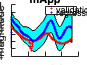

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [0.1913 0.1941 0.1969 0.1997 0.2025 0.2053 0.2082 0.2110 0.2139 0.2168 0.2197 0.2226 0.2255 0.2285 0.2315 0.2344 0.2374 0.2404 0.2434 0.2464 0.2494 0.2525 0.2555 0.2586 0.2616 0.2647 0.2677 0.2708 0.2739 0.2770 0.2801 0.2831 … ]

  Show all properties


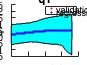

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [0.1913 0.2000 0.2085 0.2171 0.2256 0.2341 0.2425 0.2508 0.2592 0.2675 0.2757 0.2839 0.2920 0.3001 0.3081 0.3161 0.3241 0.3319 0.3398 0.3475 0.3552 0.3629 0.3704 0.3780 0.3854 0.3928 0.4002 0.4074 0.4146 0.4218 0.4288 0.4358 … ]

  Show all properties


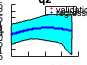

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [-0.2706 -0.2742 -0.2777 -0.2813 -0.2848 -0.2883 -0.2917 -0.2951 -0.2985 -0.3019 -0.3053 -0.3086 -0.3119 -0.3151 -0.3184 -0.3216 -0.3248 -0.3279 -0.3310 -0.3341 -0.3372 -0.3403 -0.3433 -0.3463 -0.3492 -0.3522 -0.3551 -0.3579 … ]

  Show all properties


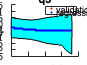

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [0.9239 0.9204 0.9168 0.9132 0.9094 0.9055 0.9015 0.8975 0.8933 0.8890 0.8846 0.8801 0.8756 0.8709 0.8661 0.8612 0.8562 0.8512 0.8460 0.8407 0.8354 0.8299 0.8244 0.8188 0.8130 0.8072 0.8013 0.7953 0.7892 0.7831 0.7768 0.7704 … ]

  Show all properties


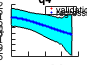

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [0.1768 0.1816 0.1865 0.1913 0.1962 0.2010 0.2058 0.2106 0.2154 0.2202 0.2250 0.2297 0.2345 0.2393 0.2440 0.2487 0.2534 0.2581 0.2628 0.2675 0.2722 0.2769 0.2815 0.2861 0.2908 0.2954 0.3000 0.3046 0.3091 0.3137 0.3182 0.3228 … ]

  Show all properties


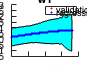

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [0.9959 0.9954 0.9949 0.9944 0.9939 0.9934 0.9928 0.9923 0.9917 0.9911 0.9905 0.9899 0.9893 0.9887 0.9881 0.9874 0.9867 0.9861 0.9854 0.9847 0.9840 0.9833 0.9826 0.9818 0.9811 0.9803 0.9795 0.9788 0.9780 0.9772 0.9764 0.9756 … ]

  Show all properties


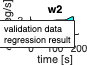

p2 =   Line with properties:

              Color: [1 0 0]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: '.'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 76 77 78 … ]
              YData: [-0.6157 -0.6149 -0.6142 -0.6134 -0.6127 -0.6119 -0.6111 -0.6102 -0.6094 -0.6085 -0.6076 -0.6067 -0.6058 -0.6048 -0.6039 -0.6029 -0.6019 -0.6009 -0.5998 -0.5988 -0.5977 -0.5966 -0.5955 -0.5944 -0.5933 -0.5921 -0.5909 -0.5897 … ]

  Show all properties


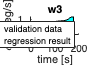

savedir = strcat(curdir, '/../results/figs/');
fignames = ["mApp", "q1", "q2", "q3", "q4", "w1", "w2", "w3"];
x_label = "time [s]";
y_labels = ["magnitude", "q1", "q2", "q3", "q4", "\omega_1 [deg/s]", "\omega_2 [deg/s]", "\omega_3 [deg/s]"];

for i = 1:1:size(fignames, 2)
    figure('Name', fignames(i));
    plot_gpr(t_valid, y_reg(:, i), y_valid(:, i), y_reg_var(:, i), fignames(i), x_label, y_labels(i), savedir)
end